%Table = readtable("Flight Data.xlsx");
% read data
[time, lat, long, speed, course, alt, temp, press, photo, RH] = readvars("Flight Data.xlsx");
data = [lat, long, speed, course, alt, temp, press, photo, RH];
feildNames = ["lat", "long", "speed", "course", "alt", "temp", "press", "photo", "RH"];
feildUnits = ["decimal?", "decimal?", "km/hr", "deg", "m", "C", "no units make sense", "raw sensor values?", "raw sensor values?"];

%rh out of 256
%p out of 256

% initial data processing

%size(data)
data = data(2:end,:); % remove strang epoint (probably it being tested)
%size(data)
%size(time)
time = time(2:end,:);
%size(time)
%convert time into elapsed time in deconds since second data point
time = convertTo(time,"epochtime","Epoch",time(1),"TicksPerSecond",1);
size(time)

ans =     92     1



%convert voltages to si units
data(6,:) = (data(6,:)./256).*500 % convert temp to kelvin

data = 	1.0e+04 *

    0.0039   -0.0095    0.0017    0.0249    0.0496    0.0141    0.0192         0    0.0131
    0.0039   -0.0095    0.0009    0.0222    0.0823    0.0142    0.0187         0    0.0116
    0.0039   -0.0095    0.0020    0.0257    0.1178    0.0140    0.0182    0.0001    0.0111
    0.0039   -0.0095    0.0033    0.0259    0.1522    0.0138    0.0176    0.0010    0.0076
    0.0039   -0.0095    0.0033    0.0247    0.2184    0.0136    0.0168    0.0003    0.0077
    0.0076   -0.0186    0.0039    0.0449    0.4951    0.0264    0.0318    0.0002    0.0160
    0.0039   -0.0095    0.0022    0.0208    0.2866    0.0135    0.0159    0.0001    0.0089
    0.0039   -0.0095    0.0030    0.0245    0.3235    0.0132    0.0154    0.0002    0.0088
    0.0039   -0.0095    0.0026    0.0250    0.3562    0.0131    0.0151    0.0012    0.0088
    0.0039   -0.0095    0.0031    0.0216    0.4266    0.0129    0.0143    0.0002    0.0094


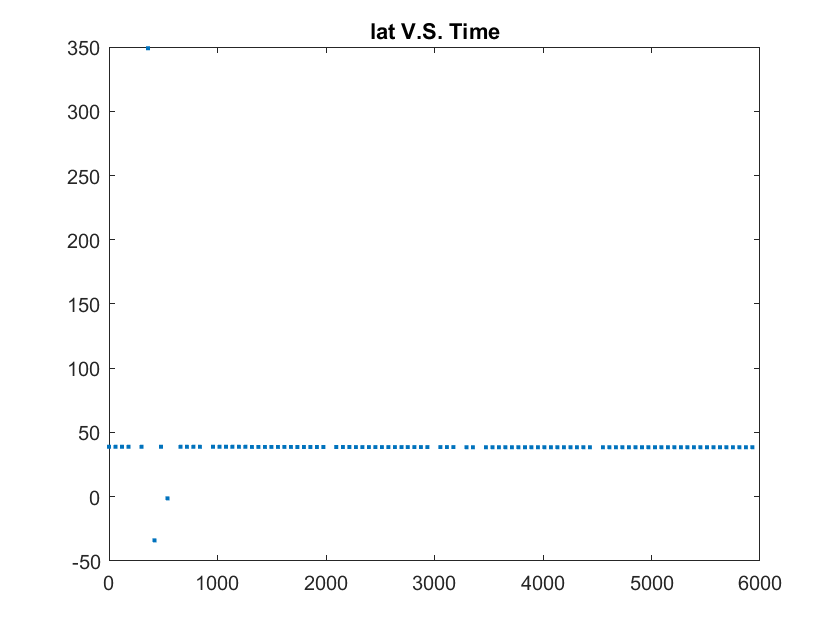

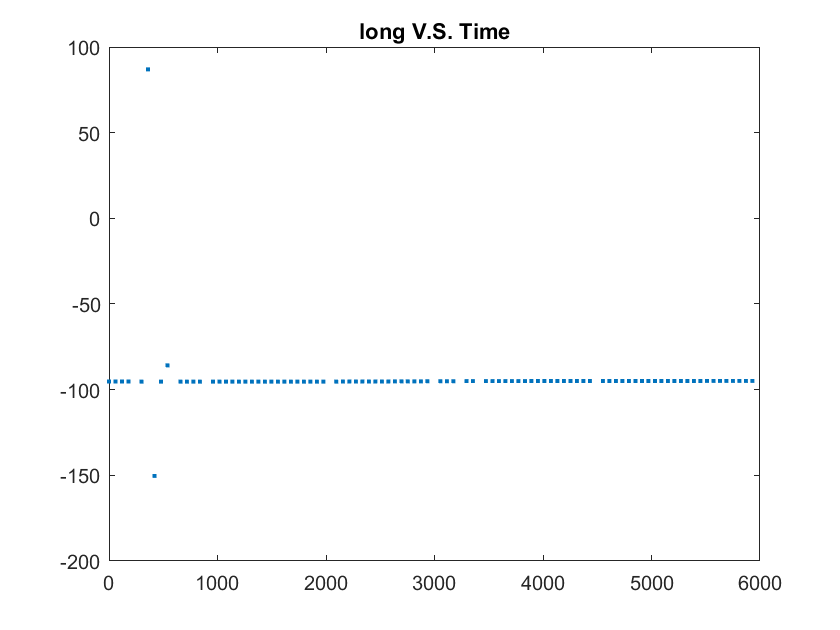

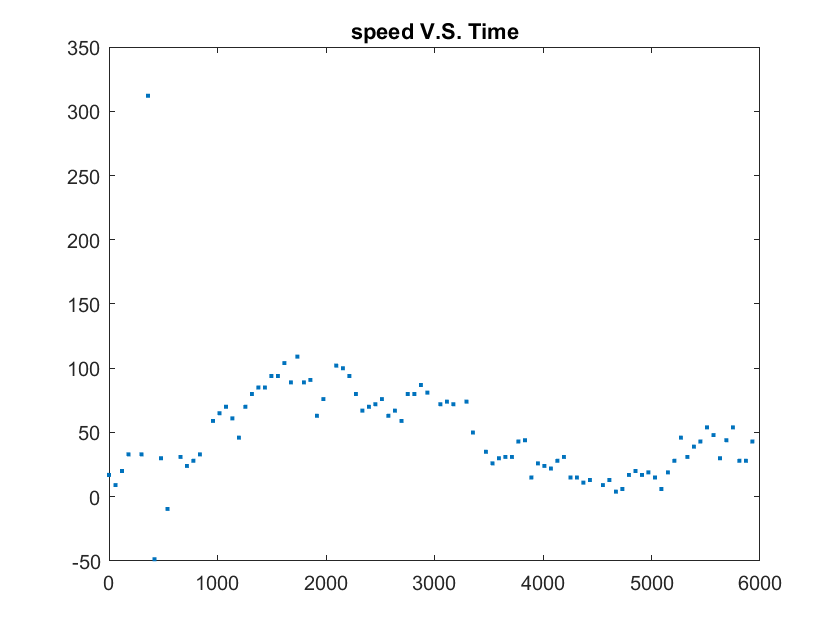

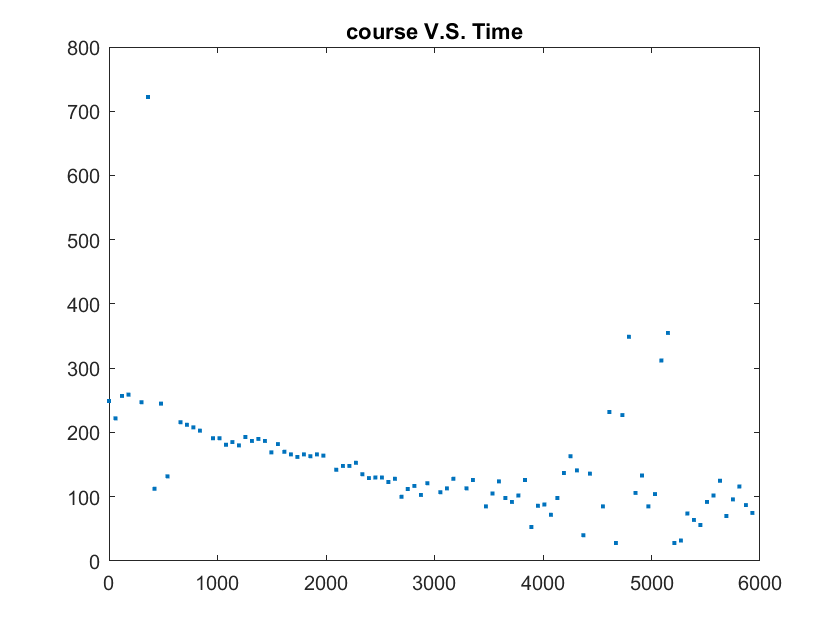

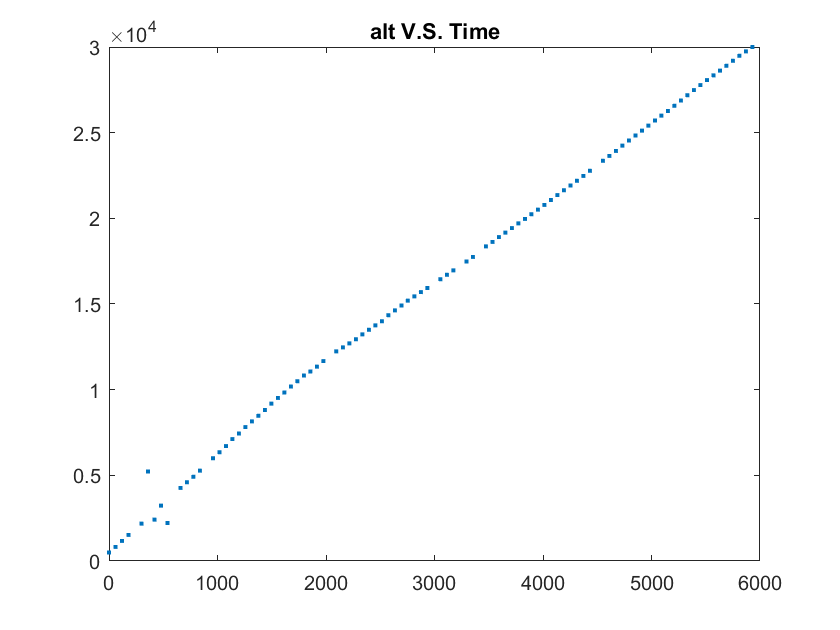

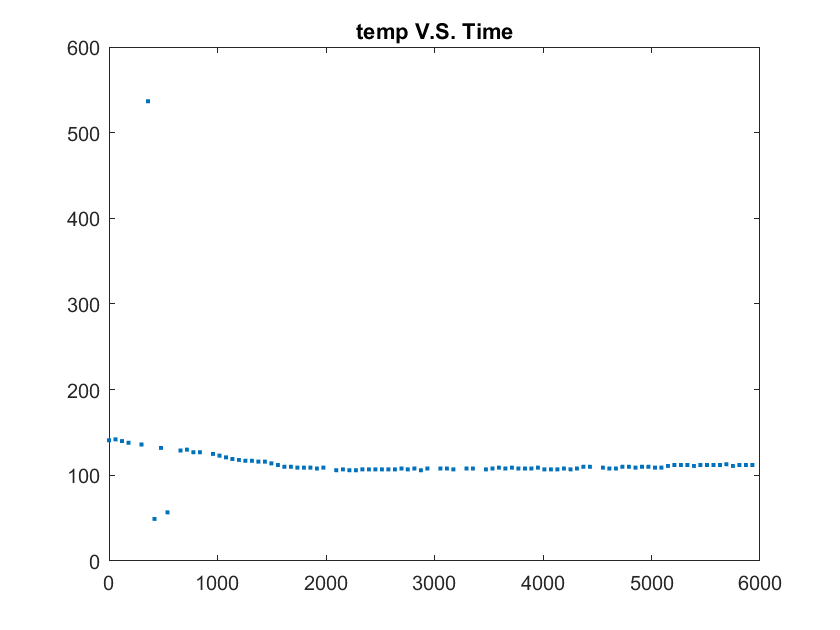

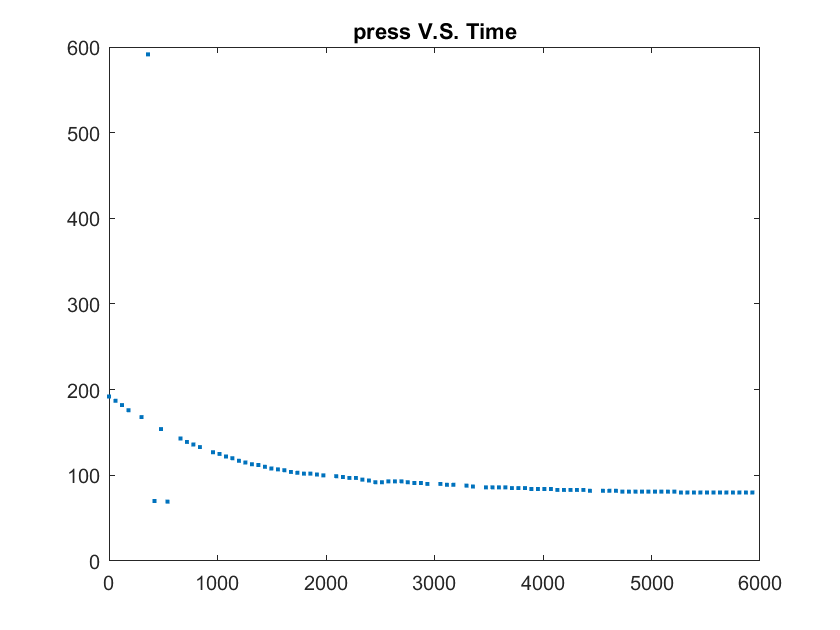

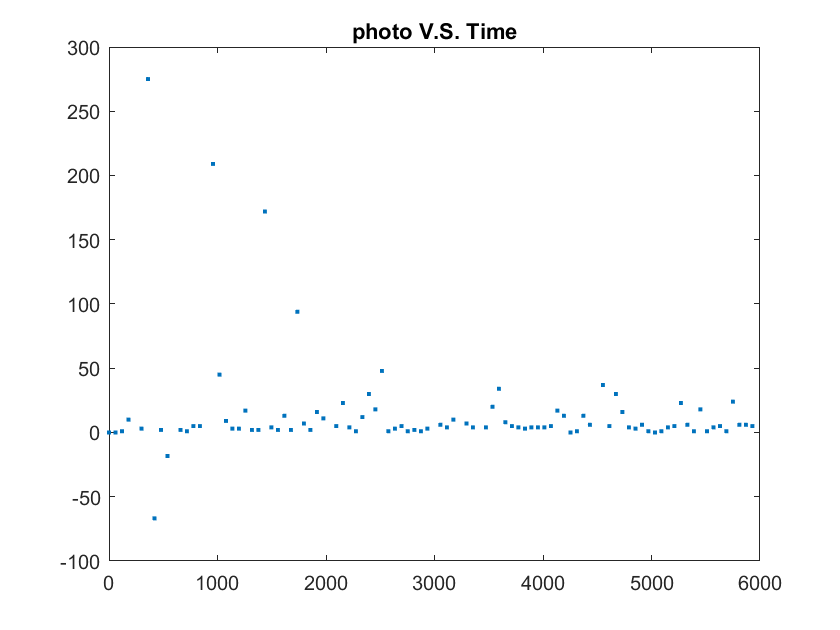

data(6,:) = data(6,:) + 273; % convert temp to degrees celcius
data(7,:) = data(7,:).*(.8665) - 67.73; % this is guess and check i thi
data(9,:) = (data(9,:) * 5/256 -.8) / .031; % convert relative humidity to %
%raw data plots
for i = 1:9
    figure
    plot(time,data(:,i),'.'); title(feildNames(i) + " V.S. Time");
end

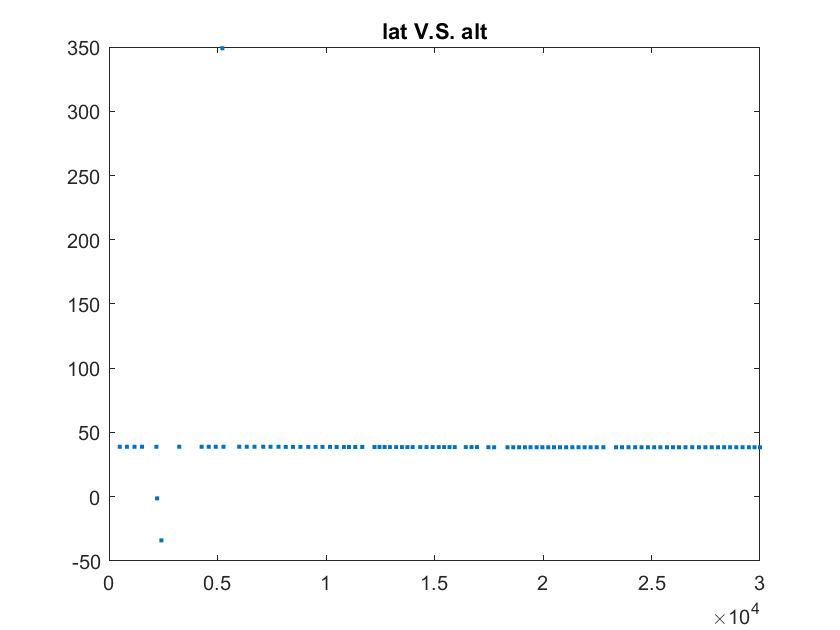

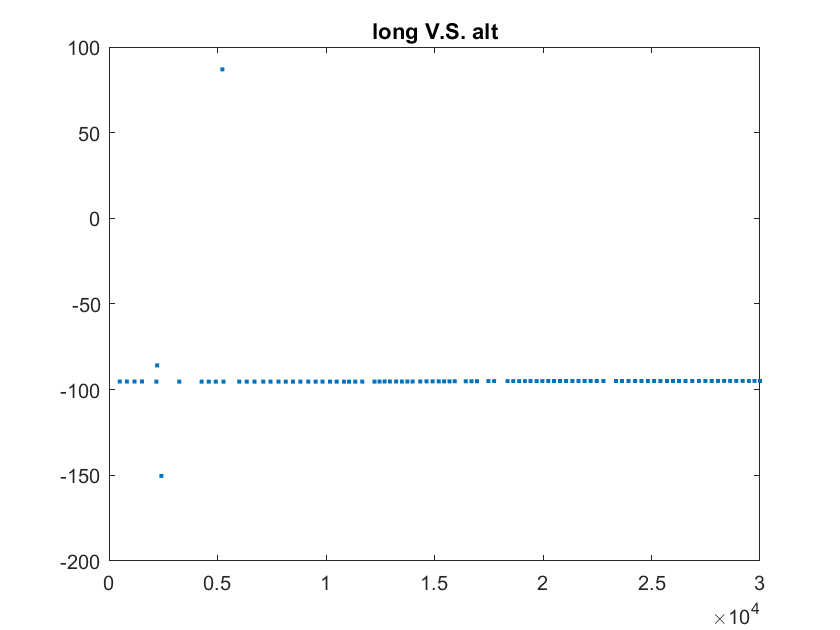

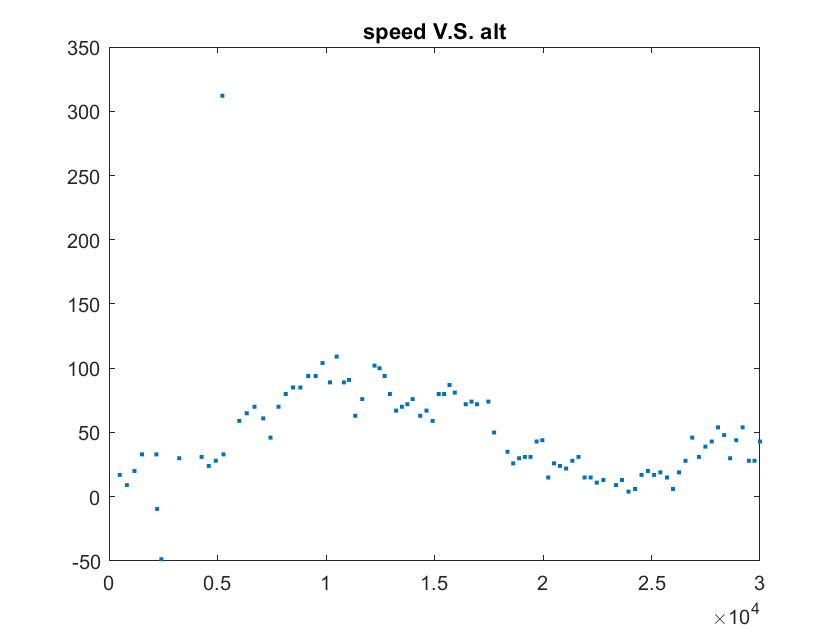

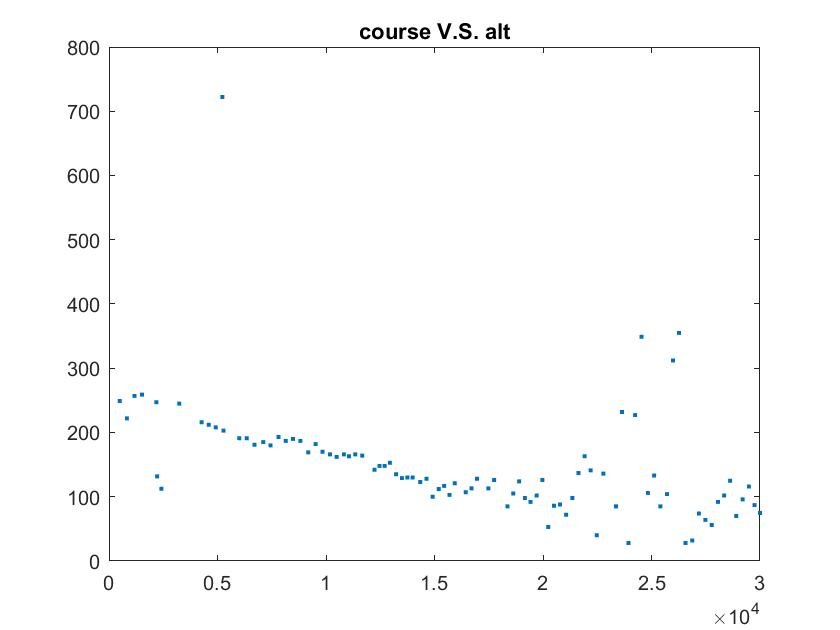

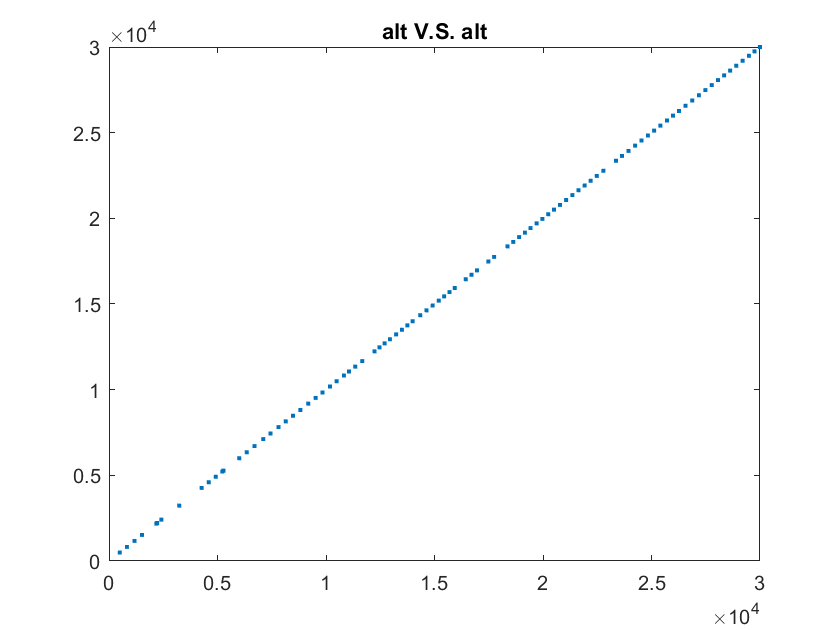

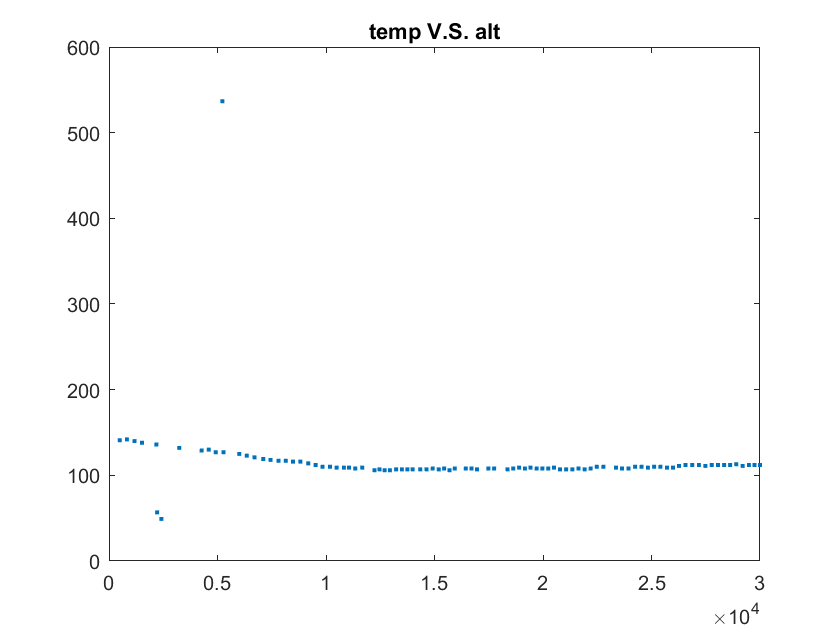

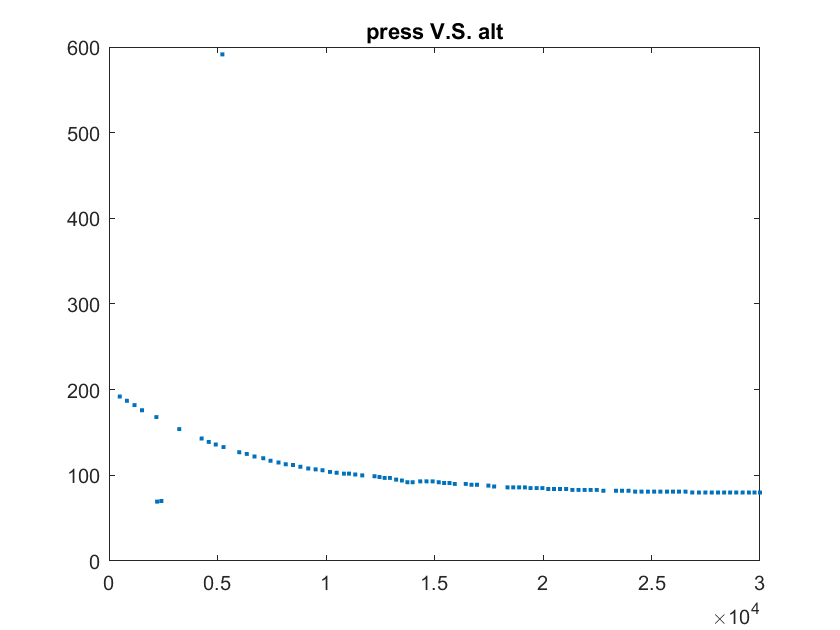

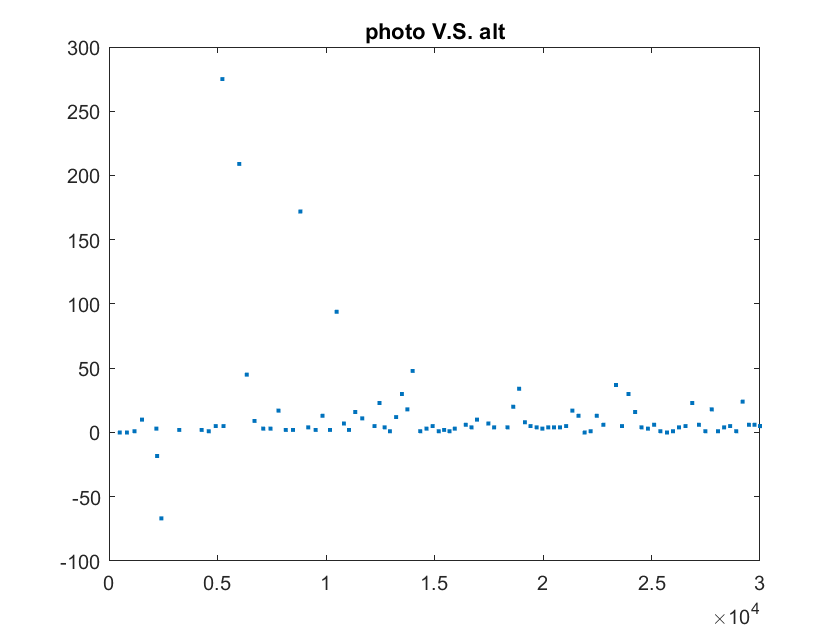


alt = data(:,5);

for i = 1:9
    figure
    plot(alt,data(:,i),'.'); title(feildNames(i) + " V.S. alt");
end

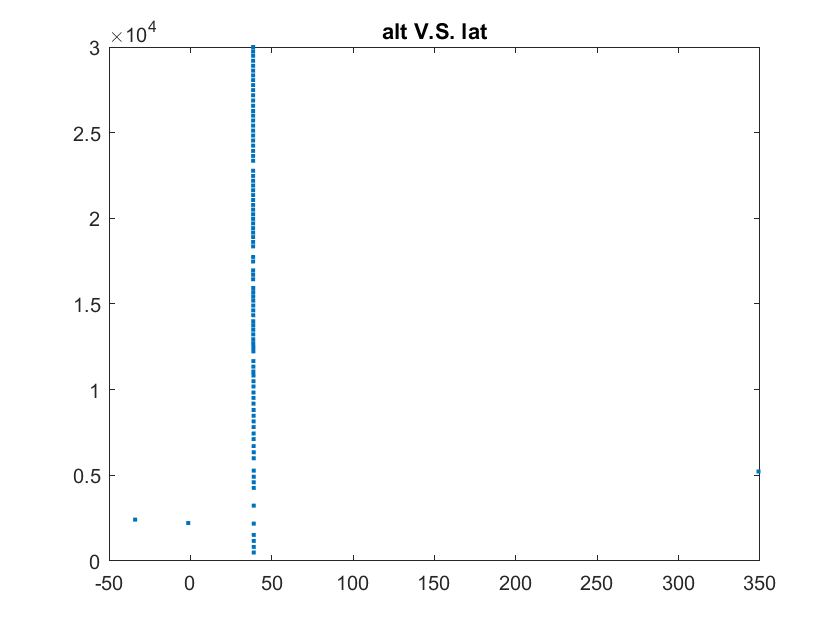

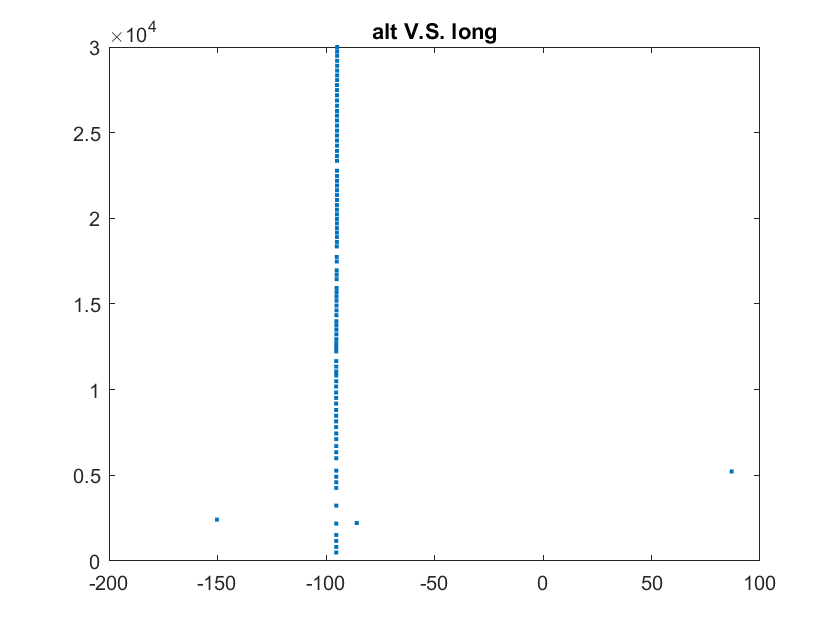

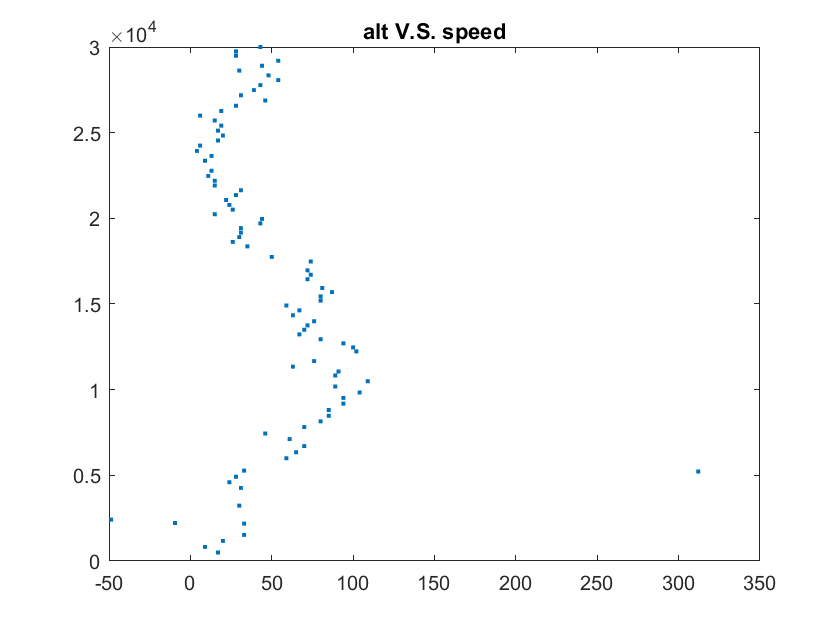

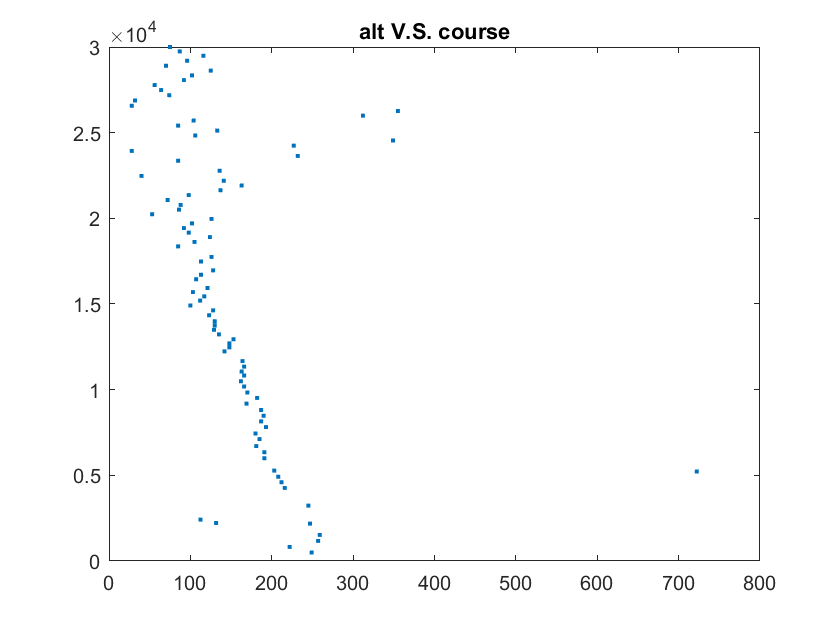

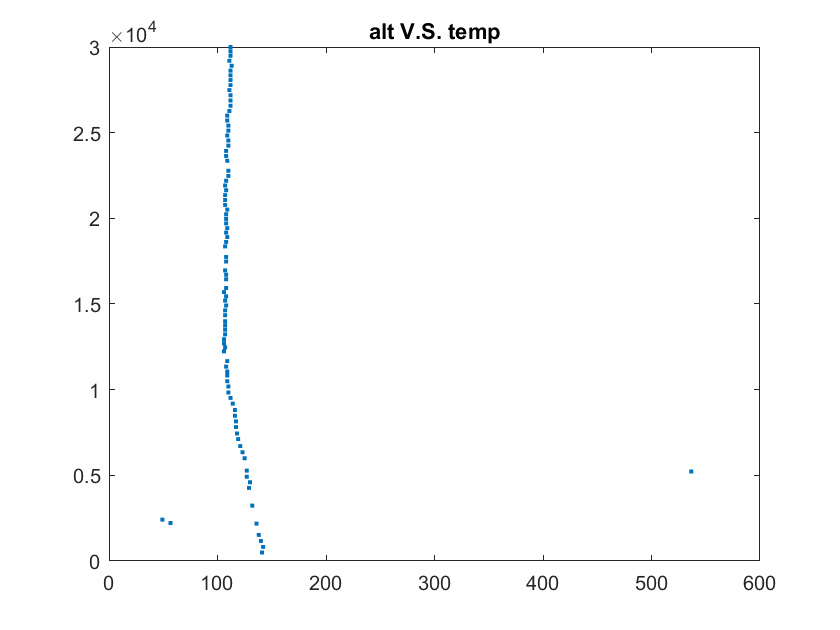

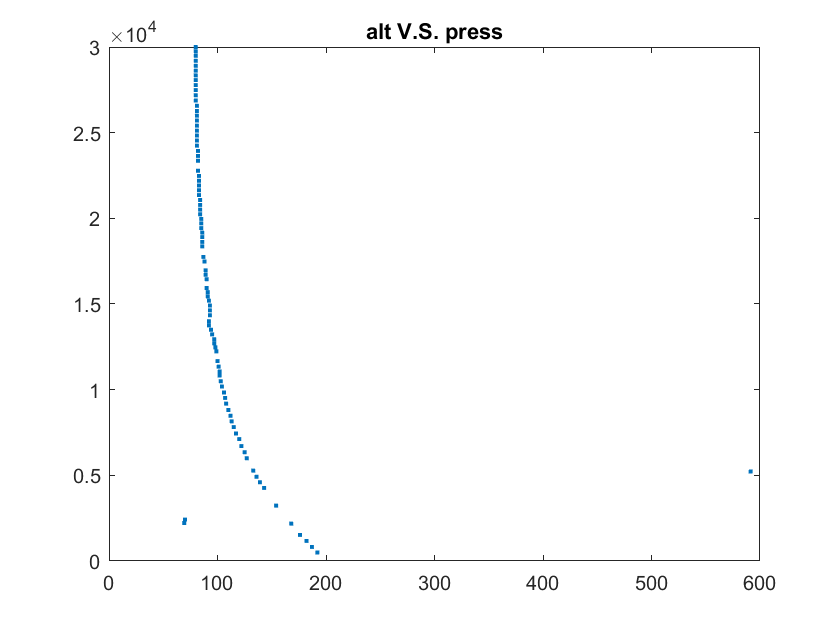

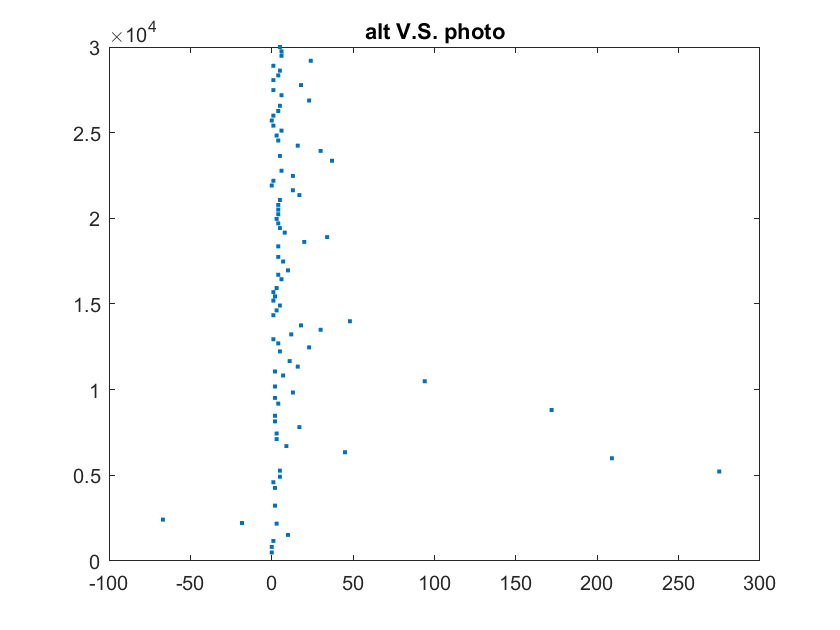

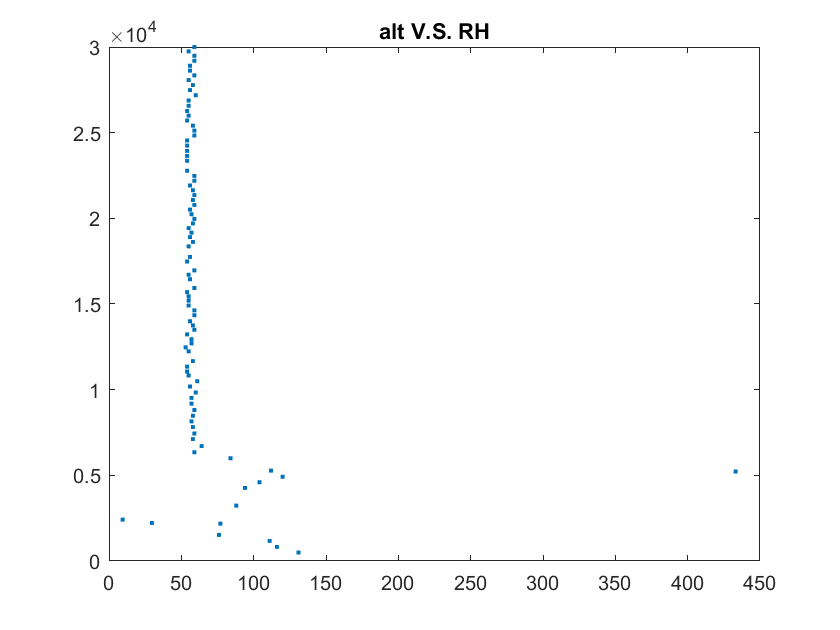


for i = 1:9
    figure
    plot(data(:,i),alt,'.'); title( "alt V.S. " + feildNames(i));
end

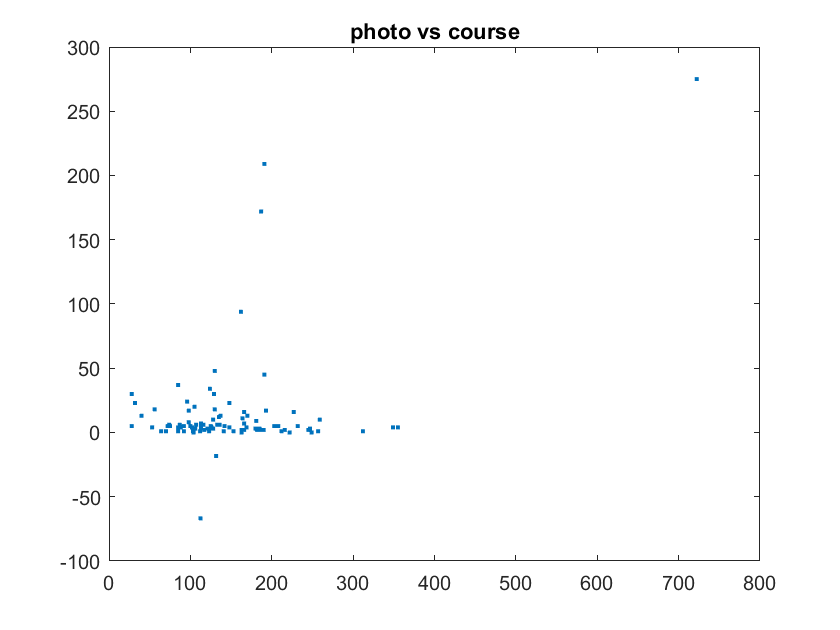


for variable = data(:,:)
    relativeVariable = variable - variable(1);
end

%t = convertTo(time,"epochtime","Epoch",time(1),"TicksPerSecond","1")

figure
plot(data(:,4), data(:,8),'.'); title("photo vs course")

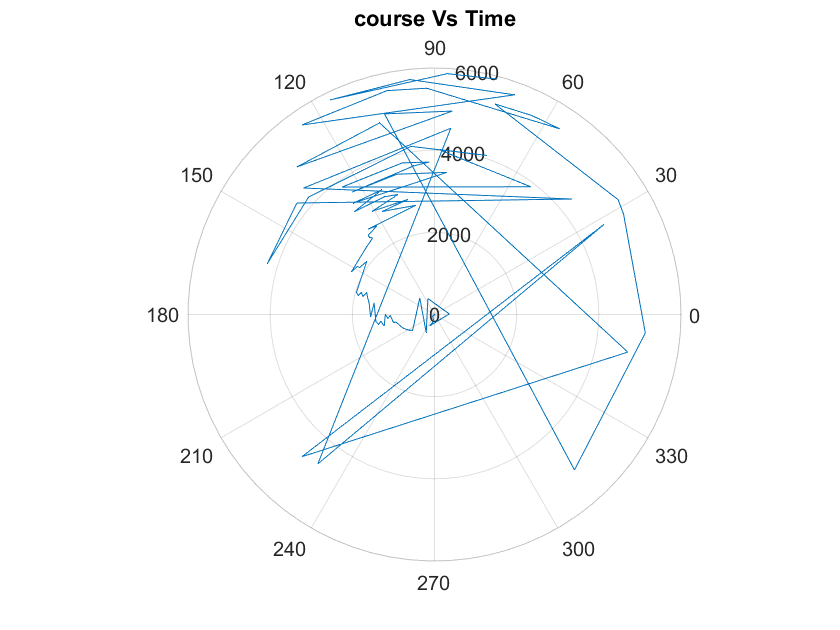


figure
polarplot(deg2rad(data(:,4)),time), grid on, title 'course Vs Time'

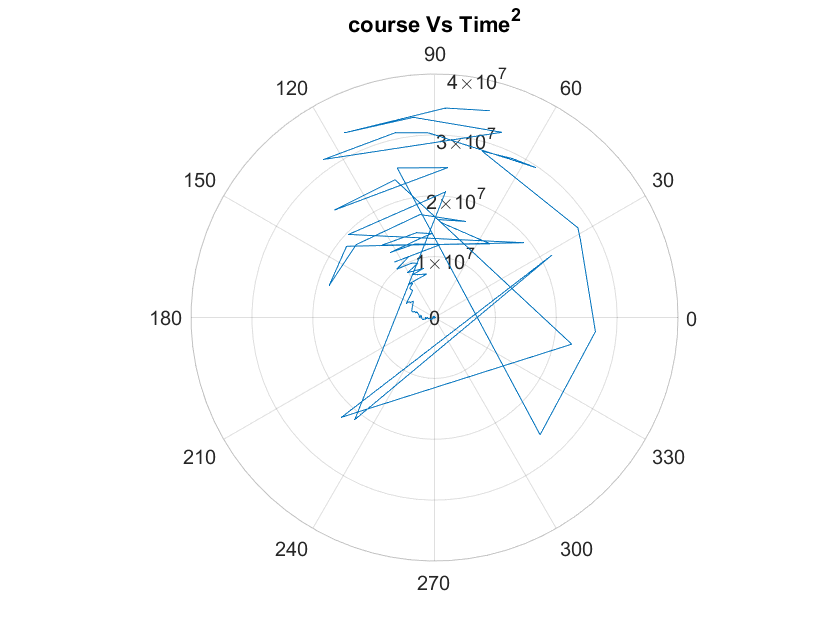


figure
polarplot(deg2rad(data(:,4)),time.^2), grid on, title 'course Vs Time^2'

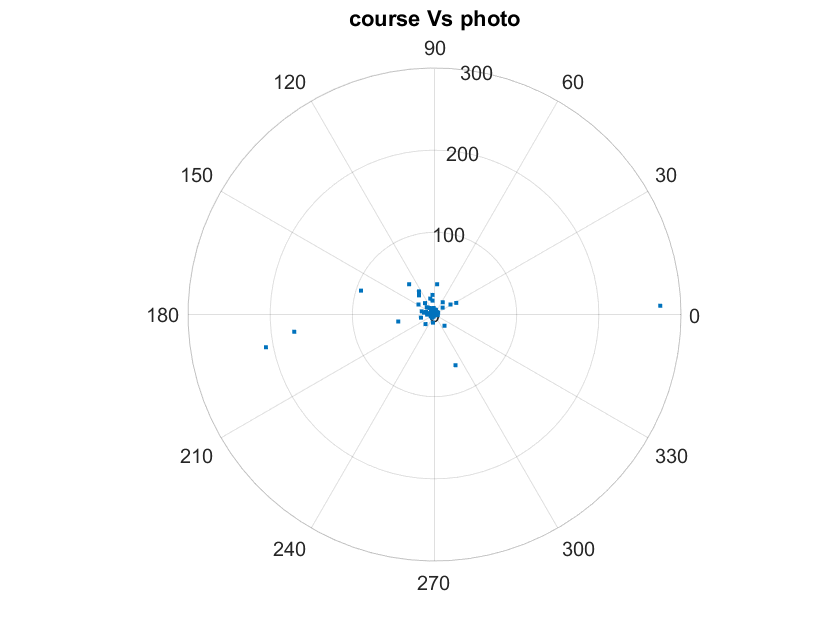


figure
polarplot(deg2rad(data(:,4)),data(:,8),'.'), grid on, title 'course Vs photo'

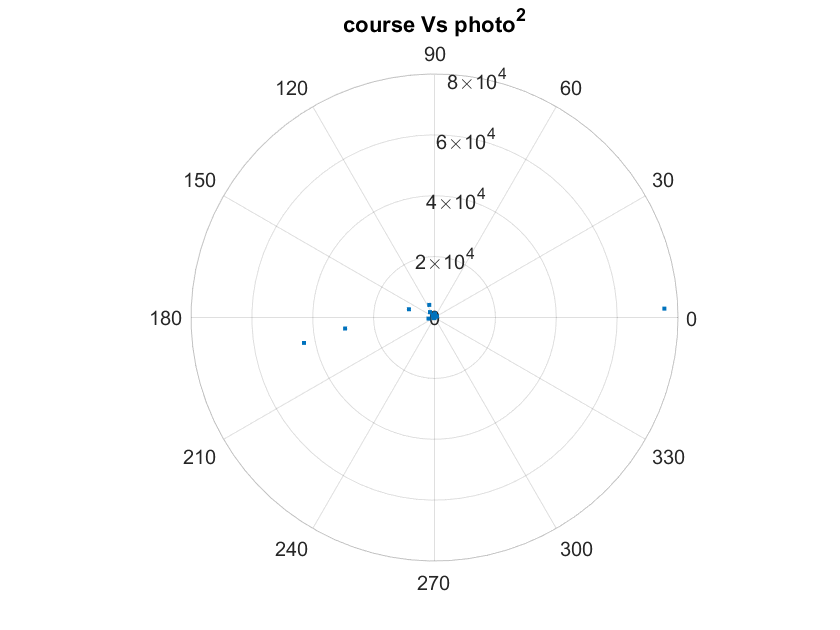


figure
polarplot(deg2rad(data(:,4)),data(:,8).^2,'.'), grid on, title 'course Vs photo^2'

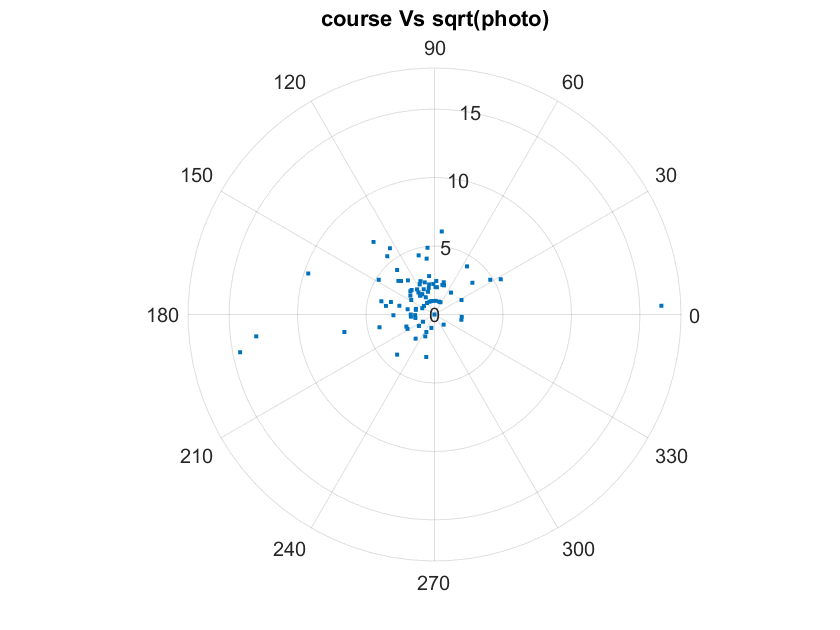


figure
polarplot(deg2rad(data(:,4)),sqrt(data(:,8)),'.'), grid on, title 'course Vs sqrt(photo)'